# 3.5. Диэлектрическая и магнитная среды

#### Соотношения между E, D и P


$$\mathit{\mathbf{D}}=\varepsilon_0 \;\mathit{\mathbf{E}}+\mathit{\mathbf{P}}=\varepsilon \;\varepsilon_0 \mathit{\mathbf{E}}$$


clear
syms rot(x) grad(x) div(x) sprod(x,y) vprod(x,y)
syms D epsilon0 E P epsilon chi_c
D==epsilon0*E+P==epsilon*epsilon0*E

$$ans = \left(\text{D}=P+\text{E}\,\epsilon_{0}\right)=\text{E}\,\epsilon \,\epsilon_{0}$$


$$\mathit{\mathbf{P}}=\left(\varepsilon -1\right)\varepsilon_0 \;\mathit{\mathbf{E}}=\chi_c \varepsilon_0 \mathit{\mathbf{E}}$$


P==(epsilon-1)*epsilon0==chi_c*epsilon0*E

$$ans = \left(P=\epsilon_{0}\,\left(\epsilon -1\right)\right)=\text{E}\,\chi_{c}\,\epsilon_{0}$$

$\chi_c$= диэлектрическая восприимчивость 

(иногдя chi_c задается так, что $\mathit{\mathbf{P}}=\chi_c \mathit{\mathbf{E}}$)

$P$ = дипольный момент единицы объема = поляризация

$\varepsilon \;\varepsilon_0$ = диэлектрическая проницаемость

$D$ = электрическое смещение = вектор электрической индукции = электрическая индукция =  вектор электрического смещения = плотноть электрического потока

#### Поверхностная плотность заряда в результате поляризации


$$\sigma_p =\mathit{\mathbf{P}}\cdot {\mathit{\mathbf{u}}}_N$$


syms sigma_p P u_N
sigma_p==P*u_N

$$ans = \sigma_{p}=P\,u_{N}$$

$u_N$= нормальный вектор

#### Соотношения между B, H и M


$$\mathit{\mathbf{B}}=\mu_0 \left(\mathit{\mathbf{H}}+\mathit{\mathbf{M}}\right)=\mu \;\mu_0 \;\mathit{\mathbf{H}}$$


syms B H M mu0 mu chi_m
B==mu0*(H+M)==mu0*mu*H

$$ans = \left(B=\mu_{0}\,\left(H+M\right)\right)=H\,\mu \,\mu_{0}$$


$$\mathit{\mathbf{M}}=\left(\mu -1\right)\mathit{\mathbf{H}}=\chi_m \mathit{\mathbf{H}}$$


M==(mu-1)*H==chi_m*H

$$ans = \left(M=H\,\left(\mu -1\right)\right)=H\,\chi_{m}$$

$\chi_m$ =  магнитная восприимчивоcть

$M$ = магнитный дипольный момент единицы объема = намагниченность

#### Теорема Гаусса для поляризуемого пространства


$$\mathrm{div}\;\mathit{\mathbf{E}}=\frac{1}{\varepsilon_0 }\left(\rho_f -\mathrm{div}\;\mathit{\mathbf{P}}\right)$$


syms E P rho_f epsilon0 rho_p
div(E)==1/epsilon0*(rho_f-div(P))

$$ans = \mathrm{div}\left(\text{E}\right)=\frac{\rho_{f}-\mathrm{div}\left(P\right)}{\epsilon_{0}}$$

$\rho_f$= объемная плотность заряда не в результате поляризации

$-\mathrm{div}\;P=\rho_p$ = плотность заряда в результате поляризации

#### Векторные компоненты поля на границах раздела

syms E_1T E_2T D_1N D_2N sigma_f H_1T H_2T B_1N B_2N
E_1T-E_2T==0, D_1N-D_2N==sigma_f, H_1T-H_2T==0, B_1N-B_2N==0

$$ans = E_{\mathrm{1T}}-E_{\mathrm{2T}}=0$$

$$ans = D_{\mathrm{1N}}-D_{\mathrm{2N}}=\sigma_{f}$$

$$ans = H_{\mathrm{1T}}-H_{\mathrm{2T}}=0$$

$$ans = B_{\mathrm{1N}}-B_{\mathrm{2N}}=0$$

% sigma_f = поверхностная плотность заряда не в результате поляризации

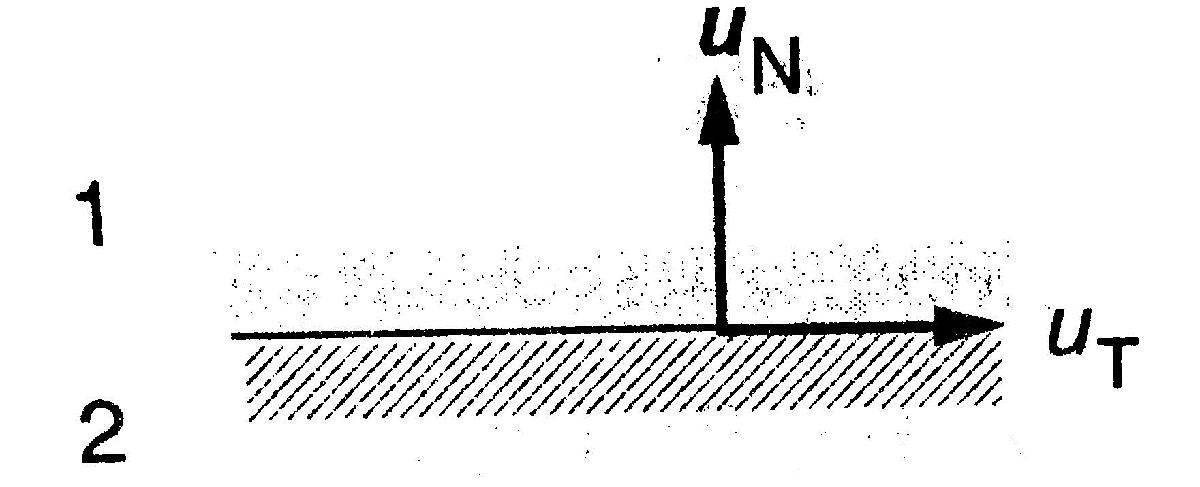

В частности, преломление магнитного поля

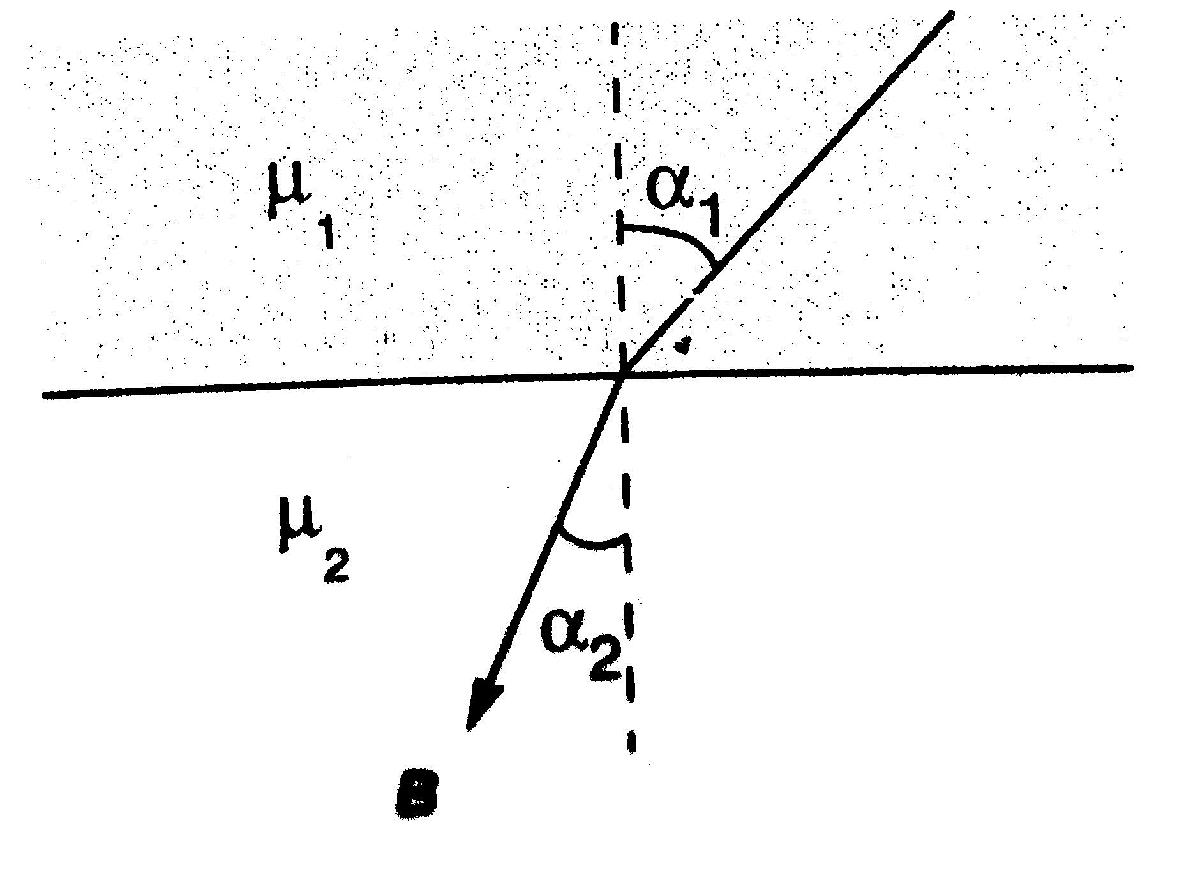

syms alpha1 alpha2 mu1 mu2
tan(alpha1)/tan(alpha2)==mu1/mu2

$$ans = \frac{\tan\left(\alpha_{1}\right)}{\tan\left(\alpha_{2}\right)}=\frac{\mu_{1}}{\mu_{2}}$$

#### Давление Максвелла

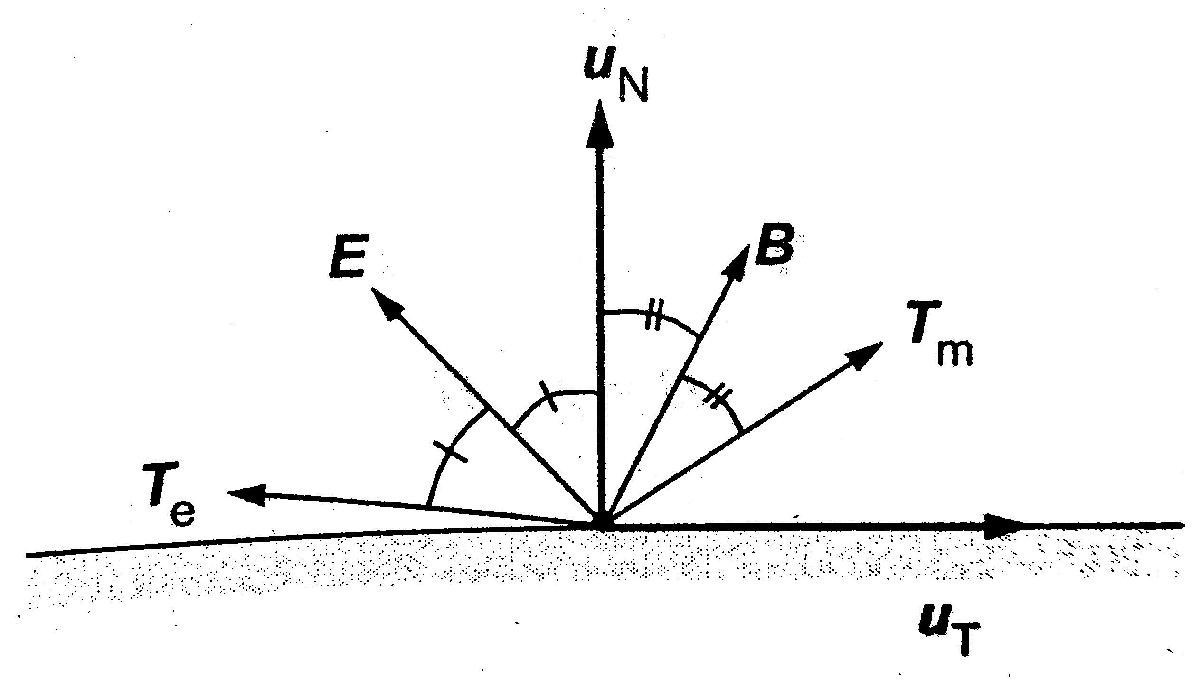

syms T_e epsilon0 E T_m mu0 B T
T_e==1/2*epsilon0*E^2

$$ans = T_{e}=\frac{{\text{E}}^{2}\,\epsilon_{0}}{2}$$

T_m==1/(2*mu0)*B^2

$$ans = T_{m}=\frac{B^{2}}{2\,\mu_{0}}$$


$$\mathit{\mathbf{T}}={\mathit{\mathbf{T}}}_e +{\mathit{\mathbf{T}}}_m$$


T==T_e+T_m

$$ans = T=T_{e}+T_{m}$$

Реальная сила


$$\mathbf{dF}=\mathit{\mathbf{T}}\;\mathrm{dA}$$


syms dF T dA
dF==T*dA

$$ans = \mathrm{dF}=T\,\mathrm{dA}$$